Load Indian Pines data and create a HSI(Hyperspectral Image) object.

We also show the three-band composite color image.

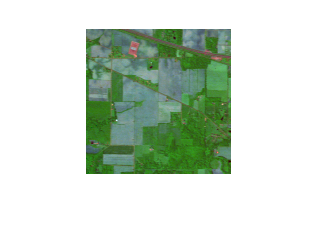

clear;
load('Data\Indian_pines.mat');
h = HSI(indian_pines);

frgb = h.him(:, :, [10, 100, 170]);
frgb = (frgb - min(frgb, [], [1, 2])) ./ ...
    (max(frgb, [], [1, 2]) - min(frgb, [], [1, 2]));
imshow(frgb);

Use .F() to flatten the 3D array to 2D array.

Use .locate() to find the desired spectra.

X = h.F();
loc = [49, 24];
d = h.locate(loc, '2D');

CEM, MF and SAM are test in this experiment.

y_CEM = CEM(X, d);
y_MF = MF(X, d);
y_SAM = SAM(X, d);

Use .result_reshape() to reshape the 1D results to 2D images.

im_CEM = h.result_reshape(y_CEM);
im_MF = h.result_reshape(y_MF);
im_SAM = h.result_reshape(y_SAM);

Imshow the results.

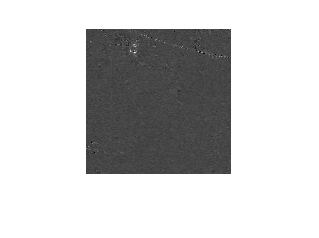

imshow(im_CEM, []);

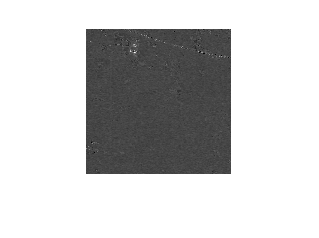

imshow(im_MF, []);

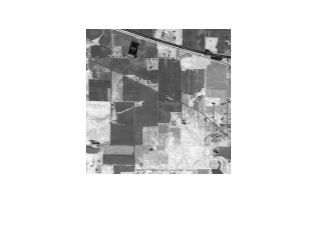

imshow(im_SAM, []);